# Application: State and Output Trajectories of LTI Systems using Laplace Transform - Example 2

## Introduction

Symbolic workflows keep calculations in their natural symbolic form rather than numerical form. This approach helps to understand the solution's properties and uses exact symbolic values. Numbers are substituted for symbolic variables only when a numerical result is required or cannot be continued in a symbolic manner.  

Typically, the steps are:

- Declare the variables and the (state and output) equations.

- Solve the equations using the Laplace transform.

- Substitute numerical values.

- Plot the results.

- Analyse the results.

## LTI System of 2nd Order: the Cart-Spring-Damper Example

We want to determine state and output trajectories for the LTI system:

        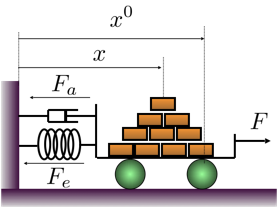     


$$\left\{ \begin{array}{rcl}
\dot{x_1}(t) &=& x_2(t)\\
\dot{x_2}(t) &=& -\frac{k}{M} x_1(t) - \frac{h}{M} x_2(t) +\frac{1}{M} u(t) \\
y(t) &=& x_1(t) 
\end{array} \right.$$


with initial condition $x_1(0) = x_0\,,\; x_2(0) = v_0$ and input $u(t) = 1+A \cos(\omega t) \cdot 1(t)\,$

### Step 0: Declare the Variables

clear

syms t s Xs Ys  % the variables 
syms x0 [2 1]                                       % in the time and frequency domain
syms k h M Au omega % parameters

assume(t >=0)
assume([k h M Au omega] >0) % a compact way to declare the parameters as positive real
                           % symbolic variables


u(t) = 1+Au * cos(omega * t) % Note: you DO NOT NEED to explicity write the Heaviside function!

$$u(t) = \mathrm{Au}\,\cos\left(\omega \,t\right)+1$$

#### Initial Conditions

Modify the initial position $x(0)$ and the initial speed $\dot{x}(0)$ of the cart and analyse the result


init_pos   = -2; % initial position [m]
init_speed = -5.5; % initial speed [m/s]

x0VAL = [init_pos; init_speed];

#### System Parameters

Note: the control law parameters $\alpha,\,\beta$ are influencing the controlled system behaviour

k_bar = 10.09; % N/m <-- nominal value  of the spring elastic constant
% Note: we do not use this parameter in the controller <--> compare with the open-loop controller

Mval = 123.52;  % kg [cart mass]
hval = 9.12;   % Ns/m [damping constant]
kval = 10.89; %k_bar;   % N/m [spring elastic coeff.] <-- change the value; use for instance k = 10.89    
% using this set of params --> roots([M h k]) complex conj.
% 

Aval = 2.50;      % magnitude of the external input force u [N]
OMval = 2*pi*0.1; % angular frequency of the input [rad/s]

### Step 1 & 2: Declare the LTI Equations in the Laplace Transform Domain and Solve them!

The most efficient way to determine statte and output trajectories of an LTI system, when the state equations are available, is to start directly with the matricial equations the Laplace transform domain.

First step: declare the matrices in the state equations. **Note**: they are symbolic matrices.

A = [    0      1;
      -k/M  -h/M];
B = [0; 1/M];
C = [1 0];
D = 0;


Then, evaluate the symbolic expression of the state and output trajectories as Laplace transforms: 

sI_A = (s*eye(size(A))-A)

$$sI\_A = \left[\begin{array}{cc} s & -1\\ \frac{k}{M} & s+\frac{h}{M} \end{array}\right]$$

sI_A_inv = inv(sI_A) % it's a symbolic matrix; do not worry about matrix inversion!

$$sI\_A\_inv = \left[\begin{array}{cc} \frac{h+M\,s}{M\,s^{2}+h\,s+k} & \frac{M}{M\,s^{2}+h\,s+k}\\ -\frac{k}{M\,s^{2}+h\,s+k} & \frac{M\,s}{M\,s^{2}+h\,s+k} \end{array}\right]$$

Now we are ready to express the state trajectory and the output trajectory using the Laplace transform


$$\left\{ \begin{array}{rcl}
X(s) &=& \left( sI-A\right)^{-1} x(0) + \left( sI-A\right)^{-1}\,B\,U(s) \\
Y(s) &=& C\,X(s) +D\,U(s)
\end{array} \right.$$


Us = laplace(u,t,s)

$$Us = \frac{1}{s}+\frac{\mathrm{Au}\,s}{\omega^{2}+s^{2}}$$

Xs = sI_A_inv * x0 + sI_A_inv * B * Us;
Ys = C * Xs + D* Us;

What does the equations look like?

disp(Xs)

$$\begin{array}{l} \left[\begin{array}{c} \frac{\frac{1}{s}+\frac{\mathrm{Au}\,s}{\omega^{2}+s^{2}}}{\sigma_{1}}+\frac{M\,x_{02}}{\sigma_{1}}+\frac{x_{01}\,\left(h+M\,s\right)}{\sigma_{1}}\\ \frac{s\,\left(\frac{1}{s}+\frac{\mathrm{Au}\,s}{\omega^{2}+s^{2}}\right)}{\sigma_{1}}-\frac{k\,x_{01}}{\sigma_{1}}+\frac{M\,s\,x_{02}}{\sigma_{1}} \end{array}\right]\\ \mathrm{where}\\ \sigma_{1}=M\,s^{2}+h\,s+k \end{array}$$

disp(Ys)

$$\frac{\frac{1}{s}+\frac{\mathrm{Au}\,s}{\omega^{2}+s^{2}}}{M\,s^{2}+h\,s+k}+\frac{M\,x_{02}}{M\,s^{2}+h\,s+k}+\frac{x_{01}\,\left(h+M\,s\right)}{M\,s^{2}+h\,s+k}$$

####  Solve the Equations Using the Laplace Transform 

Let's compute the inverse Laplace transform of the state trajectory:

xSOL_t = ilaplace(Xs);
ySOL_t = ilaplace(Ys);

What does the equation in the Laplace transform domain look like?

disp(xSOL_t)

### Step 3: Substitute Numerical Values

**Note**: In order to continue and evaluate the state and output trajectories in the time domain, we must **replace every symbolic parameter**  with the corresponding numerical value

xSol_IC = subs(xSOL_t, x0, x0VAL);
xSol_IC = subs(xSol_IC, [k h M Au omega], [kval hval Mval Aval OMval]);
xSol_IC = simplify(xSol_IC)

$$xSol\_IC = \begin{array}{l} \left[\begin{array}{c} \frac{170156250\,\sigma_{3}+28500000\,\pi \,\sigma_{2}-77200000\,\pi^{2}\,\sigma_{3}}{\sigma_{1}}-\frac{\sigma_{5}\,\left(64622068647840000\,\cos\left(\sigma_{4}\right)+13922540581455000\,\sqrt{1437}\,\sin\left(\sigma_{4}\right)-54105093013939200\,\pi^{2}\,\cos\left(\sigma_{4}\right)+11986607801696256\,\pi^{4}\,\cos\left(\sigma_{4}\right)-12214589467910400\,\sqrt{1437}\,\pi^{2}\,\sin\left(\sigma_{4}\right)+2861526948790272\,\sqrt{1437}\,\pi^{4}\,\sin\left(\sigma_{4}\right)\right)}{37557432\,\sigma_{1}}+\frac{100}{1089}\\ \frac{1250\,\pi \,\left(4560\,\pi \,\sigma_{3}-27225\,\sigma_{2}+12352\,\pi^{2}\,\sigma_{2}\right)}{\sigma_{1}}-\frac{9765625\,\sigma_{5}\,\left(\cos\left(\sigma_{4}\right)-\frac{\sqrt{1437}\,\sin\left(\sigma_{4}\right)\,\left(182552283136\,\pi^{4}-800214055200\,\pi^{2}+933171586875\right)}{17244\,\left(1678290944\,\pi^{4}-7158100800\,\pi^{2}+8153206875\right)}\right)\,\left(\frac{161955076096\,\pi^{4}}{9765625}-\frac{27630269088\,\pi^{2}}{390625}+\frac{2517710283}{31250}\right)}{193\,\sigma_{1}} \end{array}\right]\\ \mathrm{where}\\ \sigma_{1}=152571904\,\pi^{4}-651772800\,\pi^{2}+741200625\\ \sigma_{2}=\sin\left(\frac{\pi \,t}{5}\right)\\ \sigma_{3}=\cos\left(\frac{\pi \,t}{5}\right)\\ \sigma_{4}=\frac{3\,\sqrt{1437}\,t}{386}\\ \sigma_{5}={\mathrm{e}}^{-\frac{57\,t}{1544}} \end{array}$$


ySol_IC = subs(ySOL_t, x0, x0VAL); % output trajectory
ySol_IC = subs(ySol_IC, [k h M Au omega], [kval hval Mval Aval OMval]); % output trajectory
ySol_IC = simplify(ySol_IC)

$$ySol\_IC = \begin{array}{l} \frac{170156250\,\sigma_{3}+28500000\,\pi \,\sin\left(\frac{\pi \,t}{5}\right)-77200000\,\pi^{2}\,\sigma_{3}}{\sigma_{1}}-\frac{{\mathrm{e}}^{-\frac{57\,t}{1544}}\,\left(64622068647840000\,\cos\left(\sigma_{2}\right)+13922540581455000\,\sqrt{1437}\,\sin\left(\sigma_{2}\right)-54105093013939200\,\pi^{2}\,\cos\left(\sigma_{2}\right)+11986607801696256\,\pi^{4}\,\cos\left(\sigma_{2}\right)-12214589467910400\,\sqrt{1437}\,\pi^{2}\,\sin\left(\sigma_{2}\right)+2861526948790272\,\sqrt{1437}\,\pi^{4}\,\sin\left(\sigma_{2}\right)\right)}{37557432\,\sigma_{1}}+\frac{100}{1089}\\ \mathrm{where}\\ \sigma_{1}=152571904\,\pi^{4}-651772800\,\pi^{2}+741200625\\ \sigma_{2}=\frac{3\,\sqrt{1437}\,t}{386}\\ \sigma_{3}=\cos\left(\frac{\pi \,t}{5}\right) \end{array}$$

### Step 4: Plot the results.

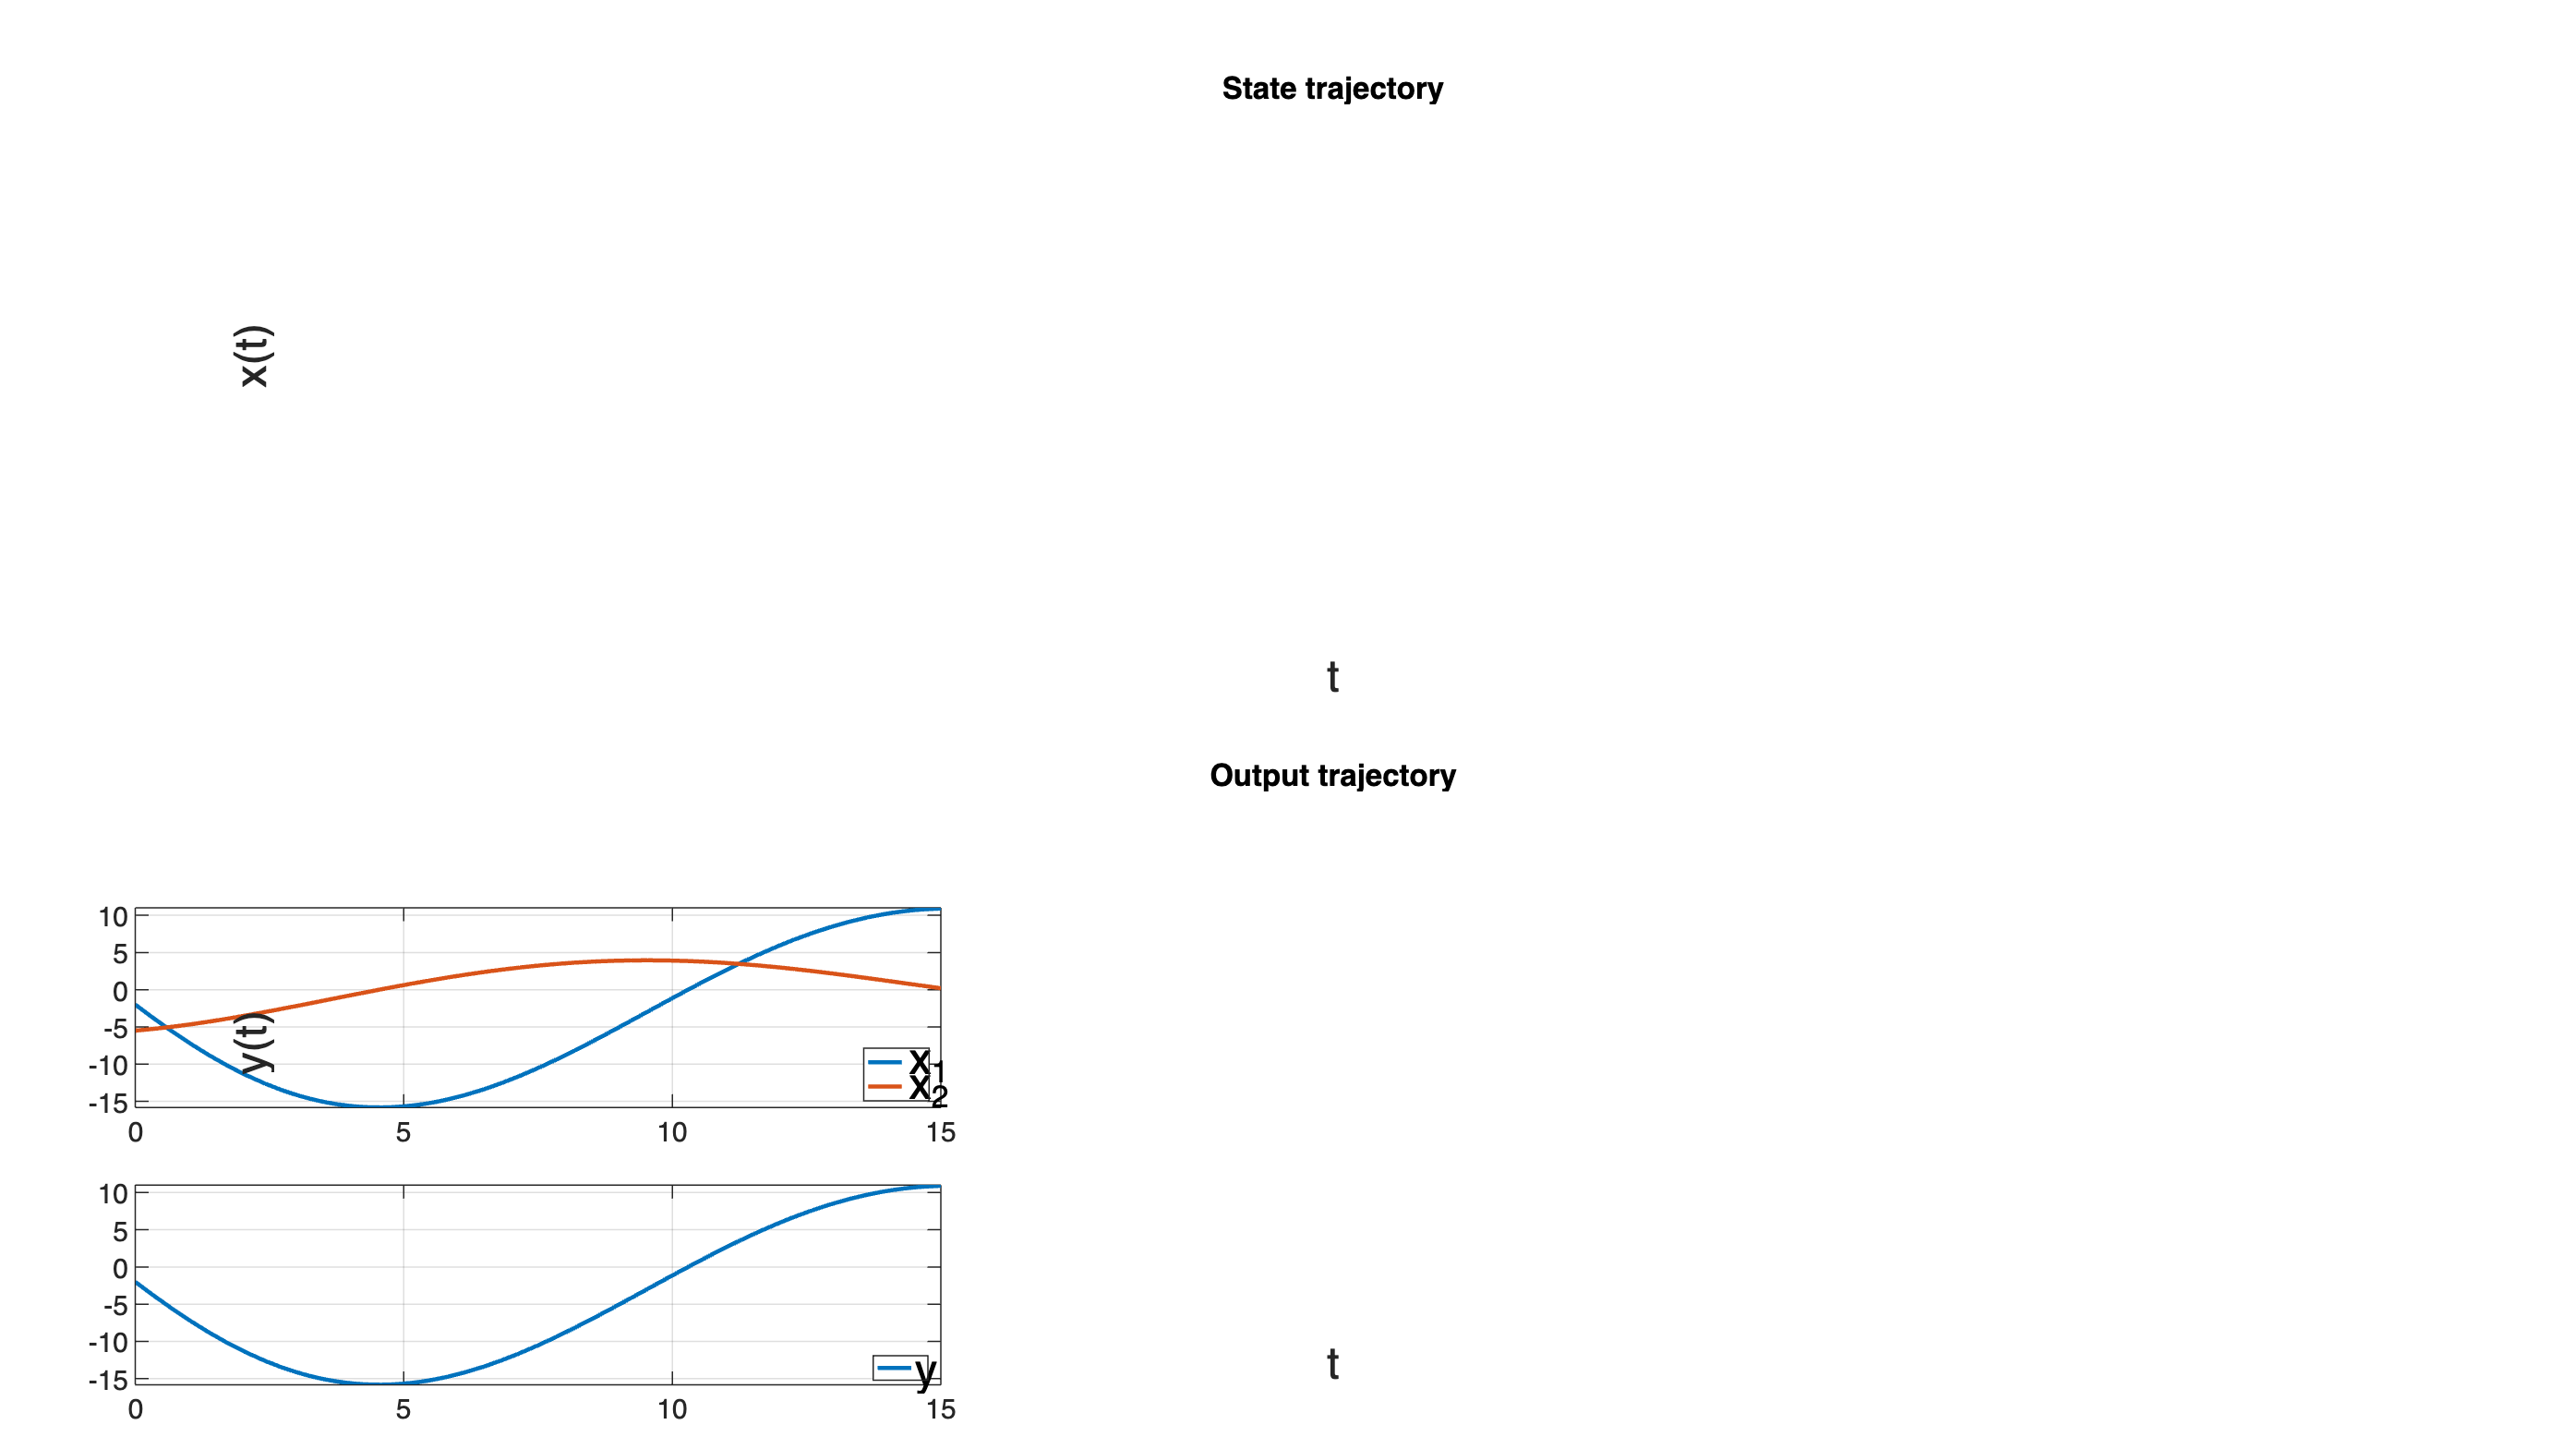

figure('Units','normalized','Position',[0.1,0.1,0.9,0.9])

subplot(2,1,1)
fplot(xSol_IC,[0 15], 'Linewidth', 1.5)                      
title('State trajectory')
ylabel('x(t)', 'FontSize', 16)
xlabel('t', 'FontSize', 16)
grid on
legend('x_1', 'x_2', 'Location', 'best', 'FontSize', 16) 
subplot(2,1,2);
fplot(ySol_IC,[0 15], 'Linewidth', 1.5)                      
title('Output trajectory')
ylabel('y(t)', 'FontSize', 16)
xlabel('t', 'FontSize', 16)
grid on
legend('y', 'Location', 'best', 'FontSize', 16) 